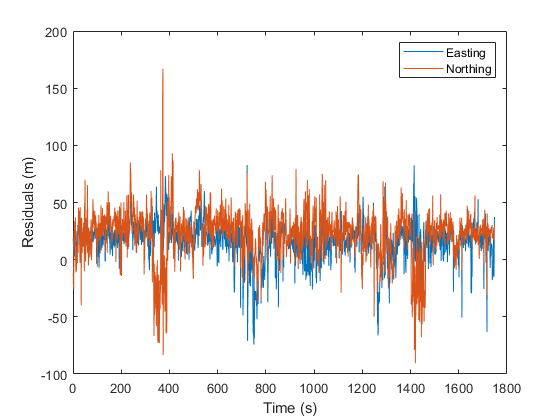

format long g
% phonename="Pixel4";
gnd=readtable("ground_truth.csv");
obsname='LLH_T.csv';
obs=readtable(obsname);
gnd{:,3}=gnd{:,3}/1000; % ms convert to s
obs{:,4}=floor(obs{:,4})

wgs84=wgs84Ellipsoid('meter');
[obsE,obsN,obsU]=geodetic2ecef(wgs84,obs{:,1},obs{:,2},obs{:,3});
[gndE,gndN,gndU]=geodetic2ecef(wgs84,gnd{:,4},gnd{:,5},gnd{:,6});
obs.E=obsE;obs.N=obsN;obs.U=obsU;
gnd.E=gndE;gnd.N=gndN;gnd.U=gndU;
gnd{:,3}=floor(gnd{:,3})
gnd=gnd(:,[1:6 12:14 7:11]);
obs=obs(:,[1:3 5:7 4]);
[ro,co]=size(obs);
vENU=NaN([ro,3]);
obsEpoch=obs{:,co}; % epoch in obs always last var
gndEpoch=gnd{:,3};

for i = 1:ro
    vENU(i,:)=obs{i,4:6}-gnd{gndEpoch==obsEpoch(i),7:9};
end
plot(vENU(:,1))
hold on
plot(vENU(:,2))
legend('Easting','Northing')
xlabel('Time (s)');ylabel('Residuals (m)');
hold off

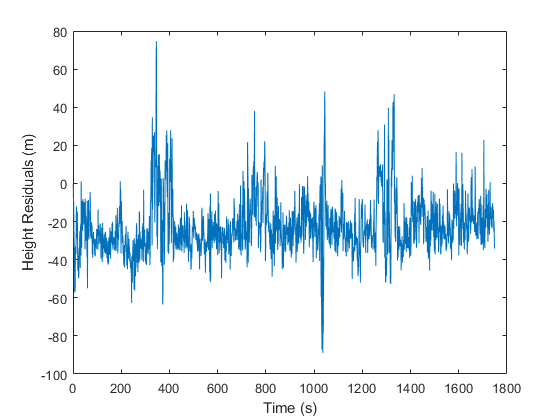

plot(vENU(:,3))
xlabel('Time (s)');ylabel('Height Residuals (m)')

rmse=sqrt(sum(vENU.^2,1,'omitnan')/ro)

rmse =           23.9927438220257          31.2860041826922          26.8425452248604


sqrt(rmse(2)^2+rmse(1)^2)

ans =           39.4267144691107


rmseH=sqrt(rmse(1)^2+rmse(2)^2)

rmseH =           39.4267144691107


rmseV=rmse(3)

rmseV =           26.8425452248604


%for i=1:
%gnd(1:10,:); % polling rate 1/s=1hz
%obs(1:10,:);

